# Metody optymalizacji - moduł 6

# Zadanie 1

### Nina Łabęcka 311339 grupa czwartek 14:15

### Dominika Pacek 311378 grupa czwartek 18:15

clc
clear

Definicje 

P = 1/8 * [7 sqrt(3); sqrt(3) 5];
xc = [1; 1];
fun = @(x) exp( x(1) + 3*x(2) - 0.1 ) + exp( -x(1) - 0.1 ) + (x - xc)' * P*(x - xc);
x0 = [2; -2];

% dokładność
eps = 1e-4

eps = 1.0000e-04


% gradient f0(x)
gradf = @(x) ...
    [
        exp( x(1) + 3*x(2) - 0.1 ) - exp( -x(1) - 0.1 );
        3*exp( x(1) + 3*x(2) - 0.1 )
    ] + 2 * P*(x - xc);

% hesjan funkcji f0(x)
hesf = @(x) ...
    [ 
        exp( x(1) + 3*x(2) - 0.1 ) + exp( -x(1) - 0.1 ),    3*exp( x(1) + 3*x(2) - 0.1 );
        3*exp( x(1) + 3*x(2) - 0.1 ),                       9*exp( x(1) + 3*x(2) - 0.1 )
    ] + 2*P;

Obliczenia metodami Newtona oraz funkcją fminsearch

[xoptn, histn] = Newton(x0, eps, gradf, hesf);
[xoptnd, histnd] = NewtonDamping(x0, eps, gradf, hesf, fun, 0.5, 0.5);
xopt = fminsearch(fun, x0);

Rysowanie poziomic

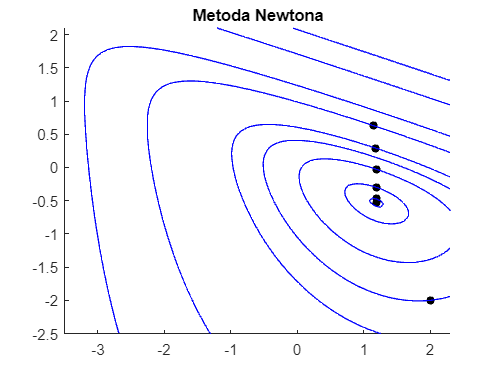

PlotContours(histn, fun, 'Metoda Newtona')

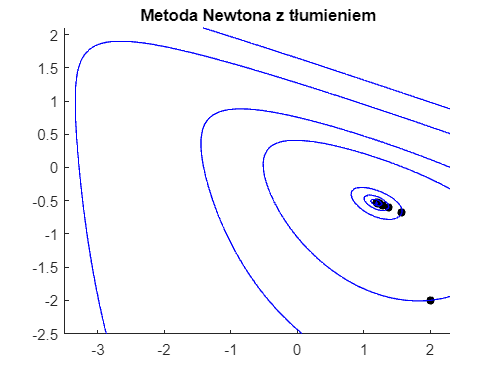

PlotContours(histnd, fun, 'Metoda Newtona z tłumieniem')

Porównanie uzyskanych wyników

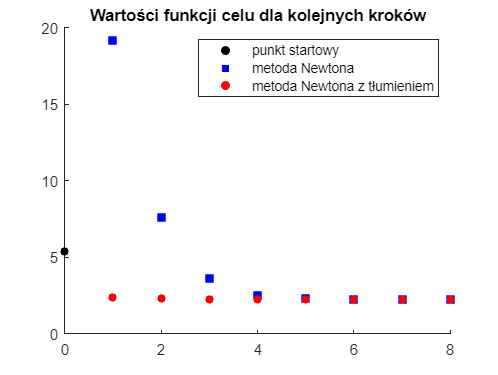

figure;
hold on;
scatter(0, fun(x0), 'filled',  'MarkerFaceColor', 'black', 'SizeData', 30, ...
    'DisplayName', 'punkt startowy');

histn_values = arrayfun(@(k) fun(histn(:, k)), 2:length(histn));
scatter(1:length(histn_values), histn_values, ...
    'filled', 's', 'MarkerFaceColor', 'b', 'SizeData', 50, ...
    'DisplayName', 'metoda Newtona');

histnd_values = arrayfun(@(k) fun(histnd(:, k)), 2:length(histnd));
scatter(1:length(histnd_values), histnd_values, ...
    'filled', 'MarkerFaceColor', 'r', 'SizeData', 30, ...
    'DisplayName', 'metoda Newtona z tłumieniem');

ylim([0, 20]);
legend();
title('Wartości funkcji celu dla kolejnych kroków')

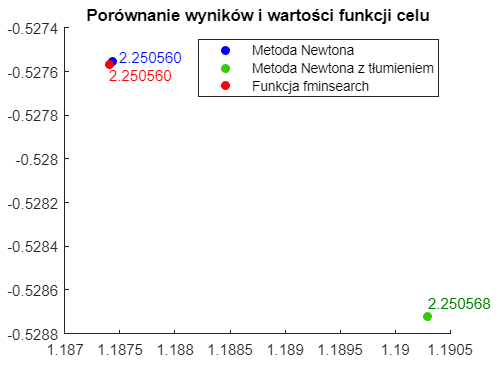

figure;
hold on;
% metoda newtona
scatter(xoptn(1), xoptn(2), 'filled', 'DisplayName', 'Metoda Newtona', ...
     'MarkerFaceColor', 'b')
text(xoptn(1) + 0.00006, xoptn(2) + 0.00002, num2str(fun(xoptn), '%.6f'), 'Color', 'b')

% metoda newtona z tłumieniem
scatter(xoptnd(1), xoptnd(2), 'filled', 'DisplayName', 'Metoda Newtona z tłumieniem', ...
    'MarkerFaceColor', [.2 .8 0])
text(xoptnd(1), xoptnd(2) + 0.00006, num2str(fun(xoptnd), '%.6f'), 'Color', [0 .5 0])

% funkcja fminsearch
scatter(xopt(1), xopt(2), 'filled', 'DisplayName', 'Funkcja fminsearch', ...
    'MarkerFaceColor', 'r')
text(xopt(1), xopt(2) - 0.00005, num2str(fun(xopt), '%.6f'), 'Color', 'r')

title('Porównanie wyników i wartości funkcji celu')
legend()

hold off;

TODO: zrobić wykres jak rysunek 4

Metoda Newtona

function [xopt, hist] = Newton(x0, eps, gradf, hesf)
    x = x0;
    hist = x;
    g = gradf(x);
    v = -inv(hesf(x)) * g;
    delta = -g' * v;
    while delta > eps
        x = x + v;
        delta = -g' * v;
        g = gradf(x);
        v = -inv(hesf(x)) * g;
        hist = [hist x];
    end
    xopt = x;
end

Metoda Newtona z tłumieniem

function [xopt, hist] = NewtonDamping(x0, eps, gradf, hesf, fun, alfa, beta)
    x = x0;
    hist = x;
    g = gradf(x);
    v = -inv(hesf(x)) * g;
    delta = -g' * v;
    while delta > eps
        s = 1;
        while fun(x + s*v) > fun(x) + s * alfa*g'*v
            s = beta*s;
        end
        x = x + s*v;
        delta = -g' * v;
        g = gradf(x);
        v = -inv(hesf(x)) * g;
        hist = [hist x];
    end
    xopt = x;
end

Funkcja do rysowania konturów

function PlotContours(points, fun, mytitle)
    figure; 
    title(mytitle)
    hold on;
    levels = [];
    for k=1:length(points)
        coords = points(:, k);
        levels = [levels fun(coords)];
        scatter(coords(1), coords(2), 'filled',  'MarkerFaceColor', 'black', 'SizeData', 30)
    end
    m = max(levels);
    levels = [levels m*2 m*8 m*24];
    s= 100;
    x1 = linspace(-3.5, 2.3, s);
    x2 = linspace(-2.5, 2.1, s);
    [X1, X2] = meshgrid(x1, x2);
    
    Z = zeros(s);
    
    for k=1:s
        for j=1:s
            x1_elem = X1(k,j);
            x2_elem = X2(k,j);
            Z(k,j) = fun([x1_elem;x2_elem]);
        end
    end
    contour(X1, X2, Z, levels, 'LineColor', 'b');
    hold off;
end